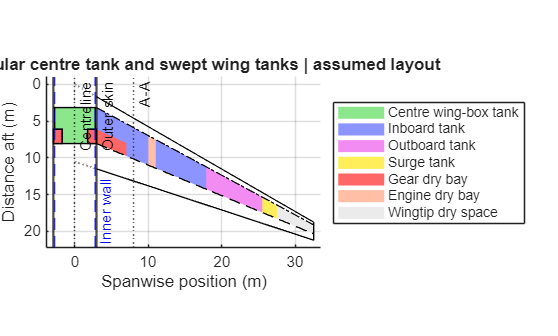

%% SC(2)-0614 wing layout and section (MATLAB R2020a or newer)
% Standalone script: airfoil coordinates are embedded below.
% Geometry source: https://m-selig.ae.illinois.edu/ads/coord/sc20614.dat
% All layout values marked ASSUMED are editable concept-design inputs.
clear; close all; clc;
folder = fileparts(mfilename('fullpath'));
if isempty(folder), folder = pwd; end

%% Inputs
p.span = 64.977;                  % m, user input
p.Sref = 422.199;                 % m^2, user input
p.rootChord = 10.54;              % m, centreline chord
p.tipChord = 2*p.Sref/p.span-p.rootChord; % preserves Sref exactly
p.sweepLE = 30;                   % degrees, ASSUMED leading-edge sweep
p.fuselageWidth = 5.868;          % m, outer diameter at wing box
p.innerDiameter = 5.513;          % m, inner diameter (plan-view limit)
p.frontSpar = 0.15;               % x/c, ASSUMED as reference image
p.rearSpar = 0.65;                % x/c, ASSUMED as reference image
p.sparWidth = 0.01;               % chord fraction, illustrative only
p.surgeLength = 2.0;             % m inboard from tip, ASSUMED, not sized
p.tipClearance = 5;              % m, ASSUMED dry space at wingtip
p.splitEta = 0.55;               % y/(b/2), ASSUMED inboard/outboard boundary
p.gearY = [p.fuselageWidth/2 7.0];             % m from centreline, ASSUMED gear bay
p.gearXC = [0.45 0.65];          % chord fractions, ASSUMED gear bay
p.gearReach = 1.2;                % m each bay extends inward from outer skin
p.gearOffset = 0;                 % m fore/aft shift of fuselage bay (+ aft)
p.engineY = [10 11];             % m, ASSUMED engine dry bay
p.sectionY = 8;                  % m, cross-section station !!!!!!!! crossection position
p.volumeFactor = 0.85;           % supplied preliminary structure allowance
p.requiredTankVolume = 129.73;   % m^3, previous estimate incl. fuel allowances

%% Embedded SC(2)-0614 coordinates (upper then lower, LE to TE)
coords = [
0.000000 0.000000;
0.002000 0.010800;
0.005000 0.016600;
0.010000 0.022500;
0.020000 0.029800;
0.030000 0.034900;
0.040000 0.038700;
0.050000 0.041800;
0.060000 0.044500;
0.070000 0.046800;
0.080000 0.048900;
0.090000 0.050800;
0.100000 0.052500;
0.110000 0.054100;
0.120000 0.055500;
0.130000 0.056800;
0.140000 0.058000;
0.150000 0.059100;
0.160000 0.060200;
0.170000 0.061200;
0.180000 0.062100;
0.190000 0.062900;
0.200000 0.063700;
0.210000 0.064400;
0.220000 0.065100;
0.230000 0.065700;
0.240000 0.066300;
0.250000 0.066800;
0.260000 0.067300;
0.270000 0.067800;
0.280000 0.068200;
0.290000 0.068600;
0.300000 0.068900;
0.310000 0.069200;
0.320000 0.069400;
0.330000 0.069600;
0.340000 0.069800;
0.350000 0.069900;
0.360000 0.070000;
0.370000 0.070100;
0.380000 0.070100;
0.390000 0.070100;
0.400000 0.070100;
0.410000 0.070000;
0.420000 0.069900;
0.430000 0.069800;
0.440000 0.069600;
0.450000 0.069400;
0.460000 0.069200;
0.470000 0.069000;
0.480000 0.068700;
0.490000 0.068400;
0.500000 0.068100;
0.510000 0.067700;
0.520000 0.067300;
0.530000 0.066900;
0.540000 0.066400;
0.550000 0.065900;
0.560000 0.065300;
0.570000 0.064700;
0.580000 0.064000;
0.590000 0.063300;
0.600000 0.062600;
0.610000 0.061800;
0.620000 0.061000;
0.630000 0.060100;
0.640000 0.059100;
0.650000 0.058100;
0.660000 0.057000;
0.670000 0.055900;
0.680000 0.054700;
0.690000 0.053500;
0.700000 0.052200;
0.710000 0.050900;
0.720000 0.049500;
0.730000 0.048100;
0.740000 0.046600;
0.750000 0.045100;
0.760000 0.043600;
0.770000 0.042000;
0.780000 0.040400;
0.790000 0.038700;
0.800000 0.037000;
0.810000 0.035200;
0.820000 0.033400;
0.830000 0.031600;
0.840000 0.029700;
0.850000 0.027800;
0.860000 0.025800;
0.870000 0.023800;
0.880000 0.021800;
0.890000 0.019700;
0.900000 0.017600;
0.910000 0.015400;
0.920000 0.013200;
0.930000 0.010900;
0.940000 0.008600;
0.950000 0.006200;
0.960000 0.003800;
0.970000 0.001300;
0.980000 -0.001300;
0.990000 -0.003900;
1.000000 -0.006600;
0.000000 0.000000;
0.002000 -0.010800;
0.005000 -0.016600;
0.010000 -0.022500;
0.020000 -0.029800;
0.030000 -0.034900;
0.040000 -0.038800;
0.050000 -0.041900;
0.060000 -0.044600;
0.070000 -0.046900;
0.080000 -0.049000;
0.090000 -0.050900;
0.100000 -0.052600;
0.110000 -0.054200;
0.120000 -0.055700;
0.130000 -0.057000;
0.140000 -0.058200;
0.150000 -0.059400;
0.160000 -0.060500;
0.170000 -0.061500;
0.180000 -0.062400;
0.190000 -0.063300;
0.200000 -0.064100;
0.210000 -0.064800;
0.220000 -0.065500;
0.230000 -0.066100;
0.240000 -0.066700;
0.250000 -0.067200;
0.260000 -0.067700;
0.270000 -0.068100;
0.280000 -0.068500;
0.290000 -0.068800;
0.300000 -0.069100;
0.310000 -0.069300;
0.320000 -0.069500;
0.330000 -0.069700;
0.340000 -0.069800;
0.350000 -0.069900;
0.360000 -0.069900;
0.370000 -0.069800;
0.380000 -0.069700;
0.390000 -0.069600;
0.400000 -0.069400;
0.410000 -0.069200;
0.420000 -0.068900;
0.430000 -0.068600;
0.440000 -0.068200;
0.450000 -0.067700;
0.460000 -0.067200;
0.470000 -0.066600;
0.480000 -0.065900;
0.490000 -0.065100;
0.500000 -0.064200;
0.510000 -0.063200;
0.520000 -0.062200;
0.530000 -0.061100;
0.540000 -0.059900;
0.550000 -0.058600;
0.560000 -0.057200;
0.570000 -0.055700;
0.580000 -0.054100;
0.590000 -0.052500;
0.600000 -0.050800;
0.610000 -0.049100;
0.620000 -0.047300;
0.630000 -0.045500;
0.640000 -0.043600;
0.650000 -0.041700;
0.660000 -0.039700;
0.670000 -0.037700;
0.680000 -0.035600;
0.690000 -0.033600;
0.700000 -0.031500;
0.710000 -0.029400;
0.720000 -0.027400;
0.730000 -0.025300;
0.740000 -0.023300;
0.750000 -0.021300;
0.760000 -0.019300;
0.770000 -0.017400;
0.780000 -0.015500;
0.790000 -0.013700;
0.800000 -0.011900;
0.810000 -0.010200;
0.820000 -0.008600;
0.830000 -0.007200;
0.840000 -0.005900;
0.850000 -0.004700;
0.860000 -0.003700;
0.870000 -0.002900;
0.880000 -0.002300;
0.890000 -0.001900;
0.900000 -0.001700;
0.910000 -0.001700;
0.920000 -0.001900;
0.930000 -0.002400;
0.940000 -0.003100;
0.950000 -0.004100;
0.960000 -0.005400;
0.970000 -0.006900;
0.980000 -0.008700;
0.990000 -0.010800;
1.000000 -0.013200;
];
upper = coords(1:103,:);
lower = coords(104:end,:);
zu = @(x) interp1(upper(:,1),upper(:,2),x,'pchip');
zl = @(x) interp1(lower(:,1),lower(:,2),x,'pchip');
halfSpan = p.span/2;
chord = @(y) p.rootChord+(p.tipChord-p.rootChord).*y/halfSpan;
le = @(y) y*tand(p.sweepLE);
% Rectangular centre box: constant section taken at the outer fuselage wall.
centreChord = chord(p.fuselageWidth/2);
centreLE = le(p.fuselageWidth/2);
centreFront = centreLE+p.frontSpar*centreChord;
centreRear = centreLE+p.rearSpar*centreChord;
assert(p.frontSpar<p.rearSpar && p.frontSpar>0 && p.rearSpar<1);
assert(p.surgeLength>0 && p.surgeLength<halfSpan-p.fuselageWidth/2);
assert(p.sectionY>=0 && p.sectionY<=halfSpan);
assert(p.splitEta*halfSpan>p.fuselageWidth/2 && ...
    p.splitEta*halfSpan<halfSpan-p.tipClearance-p.surgeLength);

%% Split the wing into non-overlapping strips at every bay boundary
edges = unique([0 p.innerDiameter/2 p.fuselageWidth/2 p.gearY p.engineY p.splitEta*halfSpan halfSpan-p.tipClearance-p.surgeLength halfSpan-p.tipClearance halfSpan]);
xc = unique([p.frontSpar p.gearXC p.rearSpar]);
names = {'Centre wing-box tank','Inboard tank','Outboard tank','Surge tank','Gear dry bay','Engine dry bay','Wingtip dry space'};
colors = [.55 .90 .55;.55 .58 1;.95 .55 .95;1 .93 .35;1 .40 .40;1 .75 .65;.92 .92 .92];
volumes = zeros(1,7);
f1 = figure('Color','w'); hold on;
handles = gobjects(1,7);
for k=1:7
    handles(k)=fill(NaN,NaN,colors(k,:),'EdgeColor','none');
end
fill([-p.innerDiameter/2 p.innerDiameter/2 p.innerDiameter/2 -p.innerDiameter/2], ...
    [centreFront centreFront centreRear centreRear],colors(1,:), ...
    'EdgeColor','k');
xb = linspace(p.frontSpar,p.rearSpar,401);
% Full central tank width is innerDiameter; upper/lower shape is constant.
volumes(1) = p.volumeFactor*p.innerDiameter*centreChord^2* ...
    trapz(xb,zu(xb)-zl(xb));
centreVolumeBeforeGear = volumes(1);
side = p.fuselageWidth/2;
wingGearX = centreLE + p.gearXC*centreChord;
p.fuselageGearX = wingGearX + p.gearOffset;
p.fuselageGearY = [side-p.gearReach side]; % right bay; mirror for left
assert(p.gearReach>0 && p.gearReach<side,'Keep the two side bays separate.');
assert(abs(p.gearOffset)<diff(wingGearX),'Keep bay openings connected at the wing root.');
tankOverlapWidth = 2*max(0,p.innerDiameter/2-p.fuselageGearY(1));
overlapFront = max(centreFront,p.fuselageGearX(1));
overlapRear = min(centreRear,p.fuselageGearX(2));
centreGearLoss = 0;
if overlapRear>overlapFront
    q = linspace((overlapFront-centreLE)/centreChord, ...
        (overlapRear-centreLE)/centreChord,401);
    % Conservative assumption: bay excludes the full local tank height.
    centreGearLoss = p.volumeFactor*tankOverlapWidth*centreChord^2* ...
        trapz(q,zu(q)-zl(q));
    volumes(1) = volumes(1)-centreGearLoss;
end
for i=1:numel(edges)-1
    y = edges(i:i+1); mid = mean(y);
    if mid<p.fuselageWidth/2, continue; end
    for j=1:numel(xc)-1
        q=xc(j:j+1); qmid=mean(q);
        if mid>=p.gearY(1) && mid<p.gearY(2) && qmid>=p.gearXC(1) && qmid<p.gearXC(2)
            k=5;
        elseif mid>=p.engineY(1) && mid<p.engineY(2)
            k=6;
        elseif mid<p.innerDiameter/2
            k=1;
        elseif mid<p.fuselageWidth/2
            continue; % exclude space between inner and outer boundaries
        elseif mid<p.splitEta*halfSpan
            k=2;
        elseif mid<halfSpan-p.tipClearance-p.surgeLength
            k=3;
        elseif mid<halfSpan-p.tipClearance
            k=4;
        else
            k=7;
        end
        fill([y fliplr(y)],[le(y)+q(1)*chord(y) fliplr(le(y)+q(2)*chord(y))],colors(k,:),'EdgeColor','none');
        c=chord(y);
        spanIntegral=diff(y)*(c(1)^2+c(1)*c(2)+c(2)^2)/3;
        xq=linspace(q(1),q(2),101);
        volumes(k)=volumes(k)+2*p.volumeFactor*spanIntegral*trapz(xq,zu(xq)-zl(xq));
    end
end
% Manually positioned rectangular landing-gear bay inside the fuselage.
gy=p.fuselageGearY; gx=p.fuselageGearX;
for sideSign = [-1 1]
fill(sideSign*[gy fliplr(gy)],[gx(1) gx(1) gx(2) gx(2)],colors(5,:), ...
    'EdgeColor','k','LineWidth',1);
end
% Exposed wing outline is solid; buried wing outline is dotted grey.
y=[p.fuselageWidth/2 halfSpan];
plot([y fliplr(y)],[le(y) fliplr(le(y)+chord(y))],'k-');
y=[0 p.fuselageWidth/2];
plot(y,le(y),':','Color',[.6 .6 .6],'LineWidth',1.2);
plot(y,le(y)+chord(y),':','Color',[.6 .6 .6],'LineWidth',1.2);
y=[p.fuselageWidth/2 halfSpan];
plot(y,le(y)+p.frontSpar*chord(y),'k-.',y,le(y)+p.rearSpar*chord(y),'k--');
plot([-p.fuselageWidth/2 p.fuselageWidth/2],[centreFront centreFront],'k-.');
plot([-p.fuselageWidth/2 p.fuselageWidth/2],[centreRear centreRear],'k--');
xline(0,'k:','Centreline');
xline(-p.innerDiameter/2,'b--','LineWidth',1);
xline(p.innerDiameter/2,'b--','Inner wall','LabelVerticalAlignment','bottom','LineWidth',1);
xline(-p.fuselageWidth/2,'k-','LineWidth',1.5);
xline(p.fuselageWidth/2,'k-','Outer skin','LabelVerticalAlignment','top','LineWidth',1.5);
xline(p.sectionY,':','A-A'); axis equal; grid on; set(gca,'YDir','reverse');
xlim([-p.fuselageWidth/2-1 halfSpan+1]);
ylim([min(-1,p.fuselageGearX(1)-1) max(le(halfSpan)+chord(halfSpan)+1,p.fuselageGearX(2)+1)]);
xlabel('Spanwise position (m)'); ylabel('Distance aft (m)');
title('Rectangular centre tank and swept wing tanks | assumed layout'); legend(handles,names,'Location','eastoutside');
print(f1,fullfile(folder,'wing_top_view.png'),'-dpng','-r200');

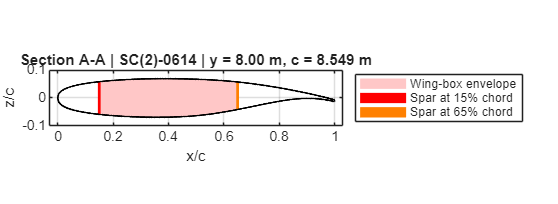

savefig(f1,fullfile(folder,'wing_top_view.fig'));

%% Cross-section at selected span station
f2 = figure('Color','w','Position',[100 180 1200 440]); hold on;
x = linspace(0,1,1000);
xb = linspace(p.frontSpar,p.rearSpar,400);
fill([xb fliplr(xb)],[zu(xb) fliplr(zl(xb))],[1 .78 .78], ...
    'EdgeColor','none','DisplayName','Wing-box envelope');
sparLocations = [p.frontSpar p.rearSpar];
colors = [1 0 0;1 .5 0];
for k=1:2
    xx = linspace(sparLocations(k)-p.sparWidth/2, ...
        sparLocations(k)+p.sparWidth/2,30);
    fill([xx fliplr(xx)],[zu(xx) fliplr(zl(xx))],colors(k,:), ...
        'EdgeColor','none','DisplayName',sprintf('Spar at %.0f%% chord',100*sparLocations(k)));
end
plot(x,zu(x),'k',x,zl(x),'k','LineWidth',1.2,'HandleVisibility','off');
plot([1 1],[zl(1) zu(1)],'k','HandleVisibility','off');
axis equal; xlim([-.03 1.03]); ylim([-.10 .10]); grid on; box on;
xlabel('x/c'); ylabel('z/c');
sectionChord = chord(p.sectionY);
if p.sectionY<p.fuselageWidth/2, sectionChord = centreChord; end
title(sprintf('Section A-A | SC(2)-0614 | y = %.2f m, c = %.3f m', ...
    p.sectionY,sectionChord));
legend('Location','eastoutside');
print(f2,fullfile(folder,'wing_cross_section.png'),'-dpng','-r200');

savefig(f2,fullfile(folder,'wing_cross_section.fig'));

%% Volume report: bilateral values, centre box counted once in full span
fprintf('\nIllustrative layout only: surge and dry bays are assumed.\n');


Illustrative layout only: surge and dry bays are assumed.


fprintf('Root chord %.4f m; derived tip chord %.4f m; Sref %.3f m^2\n', ...
    p.rootChord,p.tipChord,p.Sref);

Root chord 10.5400 m; derived tip chord 2.4553 m; Sref 422.199 m^2


fprintf('Rectangular centre tank: width %.3f m, fore-aft length %.3f m\n', ...
    p.innerDiameter,centreRear-centreFront);

Rectangular centre tank: width 5.513 m, fore-aft length 4.905 m


fprintf('Centre-box height profile assumed constant from fuselage-side airfoil.\n');

Centre-box height profile assumed constant from fuselage-side airfoil.


fprintf('Centre tank before fuselage gear bay: %.2f m^3\n',centreVolumeBeforeGear);

Centre tank before fuselage gear bay: 29.26 m^3


fprintf('Centre tank loss from fuselage gear bay: %.2f m^3\n',centreGearLoss);

Centre tank loss from fuselage gear bay: 4.09 m^3


for k=1:3, fprintf('%s, full aircraft: %.2f m^3\n',names{k},volumes(k)); end

Centre wing-box tank, full aircraft: 25.17 m^3
Inboard tank, full aircraft: 84.46 m^3
Outboard tank, full aircraft: 22.50 m^3


fprintf('Surge envelope after volume factor, BOTH wings: %.2f m^3\n',volumes(4));

Surge envelope after volume factor, BOTH wings: 3.44 m^3


fprintf('Total tank envelope excluding surge: %.2f m^3\n',sum(volumes(1:3)));

Total tank envelope excluding surge: 132.13 m^3


fprintf('Required tank envelope: %.2f m^3; difference: %+.2f m^3\n', ...
    p.requiredTankVolume,sum(volumes(1:3))-p.requiredTankVolume);

Required tank envelope: 129.73 m^3; difference: +2.40 m^3


fprintf('The 0.85 factor covers unresolved structure; avoid counting resolved structure twice.\n');

The 0.85 factor covers unresolved structure; avoid counting resolved structure twice.


fprintf('Section fill shows envelope; spar widths are illustrative, not strength sizing.\n');

Section fill shows envelope; spar widths are illustrative, not strength sizing.
